close all;
clearvars;
clc;

dir = uigetdir('default','Pilih Folder Data Training');

imds = imageDatastore(dir, ...
    'LabelSource',...
    'foldernames',...
    'IncludeSubfolders',...
    true);

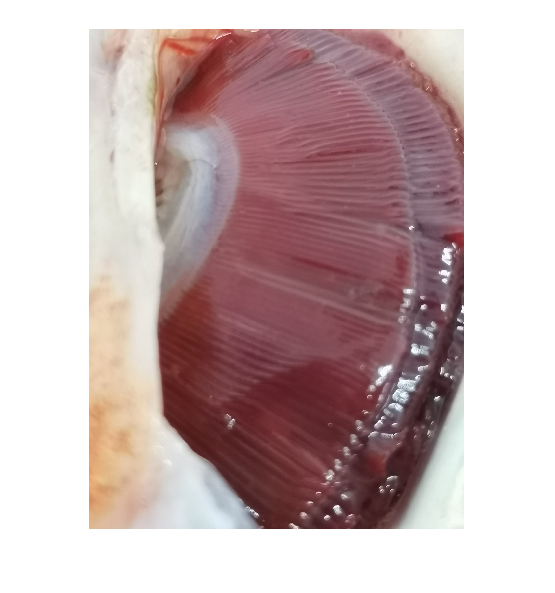

% Find the first instance of an image for each category
segar = find(imds.Labels == 'Segar', 1);

figure
imshow(readimage(imds,segar))

tbl = countEachLabel(imds)

tbl = 2×2 table
       Label       Count
    ___________    _____

    Segar           36  
    Tidak Segar     36  


% Load pretrained network
net = resnet50();

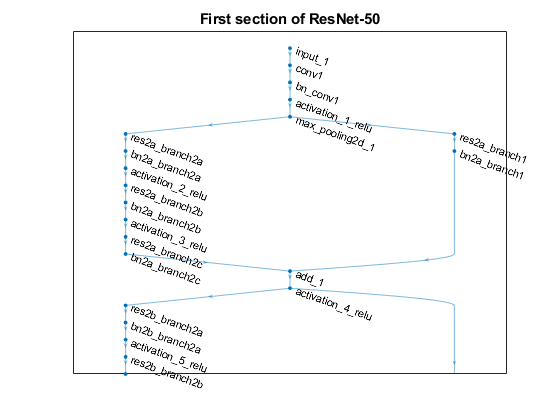

% Visualize the first section of the network. 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input_1'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


% Inspect the last layer
net.Layers(end-2)

ans =   FullyConnectedLayer with properties:

          Name: 'fc1000'

   Hyperparameters
     InputSize: 2048
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×2048 single]
          Bias: [1000×1 single]

  Show all properties


% Number of class names for ImageNet classification task
numel(net.Layers(end).ClassNames)

ans = 1000

[trainingSet, testSet] = splitEachLabel(imds, 0.7, 'randomize');

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');

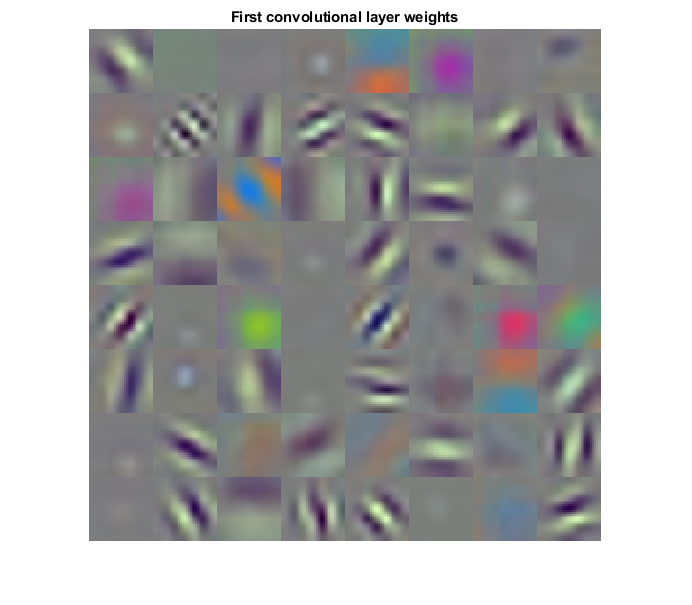

% Get the network weights for the second convolutional layer
w1 = net.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5); 

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w1)
title('First convolutional layer weights')

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32,...
    'OutputAs', 'rows');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'rows');

% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.9091    0.0909
    0.0909    0.9091


% Display the mean accuracy
mean(diag(confMat))

ans = 0.9091